# Overview and Motivation

*This example uses a fictional scenario based on a typical engineer's experience for the purpose of demonstration. Any use of names of actual products or firms is entirely coincidental and unintentional. The contents of this example do not constitute a complete, production-ready design.*

*This example was created using MATLAB*®* R2018b.*

*Copyright 2019 The MathWorks, Inc.*

You are an engineer at ***Farnswerth Automotive*** and are on a secret project team developing a single-occupant [Level 5 autonomous vehicle](https://www.caranddriver.com/features/a15079828/autonomous-self-driving-car-levels-car-levels/), which many call **The Pod**. You recently completed work on a prototype called **Destiny, **which was a Level 4 vehicle.

Your team, which designs the control system software, is about to complete the "desktop simulation" phase of the project before moving on to the much-anticipated "hardware in the loop" testing phase in the brand new **state-of-the-art** testing facility hidden away from the rest of the company. Everyone is excited!

One of your many responsibilities is the adaptive cruise control feature, which should set **The Pod** apart from its competition because it will allow multiple Pods to travel within 1 meter of each other at 100 km/h. The Farnswerth Automotive CEO has been posting about this specific feature on social media for months now.

You have completed most of the design, and have saved the "easy stuff" for the very end. This part of the design is a simple modification of an older cruise control design from the **Destiny **program. Using an older design as the baseline can save you time.

[**Click here**](matlab:open_destiny_model;) to open the model we will be modifying, or run the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

open_system('CruiseControl_Destiny')

We will be modifying this model to meet the requirements of **The Pod** program.

Before our new design can be integrated into the rest of the control system software, we will need to make sure the design :

- meets requirements

- is compliant with Farnswerth Automotive modeling standards

- is free of errors.

In this example workflow, we will use a few of the Verification and Validation tools from The MathWorks**®** to accomplish these goals.

We will be using the following MathWorks products:

[**Simulink® Requirements™**](https://www.mathworks.com/products/simulink-requirements.html) to manage requirements in the Simulink environment

[**Simulink® Check™**](https://www.mathworks.com/products/simulink-check.html) to ensure compliance with modeling standards, including custom Farnswerth Automotive checks

[**Simulink® Design Verifier™**](https://www.mathworks.com/products/sldesignverifier.html) to ensure the model is free from run-time errors

This example assumes that the user has a basic knowledge of [**Simulink®**](https://www.mathworks.com/products/simulink.html) and [**Stateflow®**](https://www.mathworks.com/products/stateflow.html).

# Part 1: Managing Requirements in Simulink®

The new design will be a simple modification of an existing design, with some minor requirements changes. This is commonly referred to as a "**requirements change**" workflow.

**Simulink® Requirements™ **is used to view and author requirements within Simulink®, as well as to establish traceability between requirements, Simulink® models, and test cases to understand the impact of a change in requirements.

In a typical requirements change workflow with Simulink®, the user would need to import a requirements change from an external tool. In this workflow, we will work with requirements that have already been imported into Simulink® using Simulink® Requirements™.

These requirements have already been reviewed by you and your team on **The Pod **program.

## **Step 1: Open the Requirements Documents to View Changes**

Let's first take a look at the requirements for **The Pod**, which have been exported from a third party requirements management tool into a Microsoft® Excel™ spreadsheet. We will use Microsoft® Excel™ to view the two different requirement sets to understand the changes, and will make the requirements changes directly in Simulink® using Simulink® Requirements™.

Open the spreadsheet by [**clicking here**](matlab:open_syssreq_pod;) or by running the following code (click **Run Section **in the Live Editor toolstrip):

pod_requirements_file = 'SystemReqs_Pod.xlsx';
if ispc
    winopen(pod_requirements_file);
else
    system(['open ', pod_requirements_file]); 
end

Let's compare these requirements with the requirements from the **Destiny** program. [**Click here**](matlab:open_syssreq_orig;) to open a spreadsheet with the **Destiny** requirements, or by running the following code:

destiny_requirements_file = 'SystemReqs_Original.xlsx';
if ispc
    winopen(destiny_requirements_file);
else
    system(['open ', destiny_requirements_file]); 
end

Look at the following requirements from the **Destiny** program:

**INTF-1**: "A hardware switch shall be used that has four (4) individual button inputs to:  (1) power on/off (2)  dual function set/decrease speed (3) dual function resume/increase speed **(4) Cancel active cruise control mode**"

**FUNC-7**: "Pressing the Cancel switch will immediately deactivate the cruise controller and return full control to the driver."

**The Pod** program does not need the Cancel switch. Instead, only the **Brake** signal will be used to disengage cruise control. The Brake signal is calculated in a brand new Simulink® model, which we will not need to change as part of this workflow. For the time being, the Brake signal in the model will retain its original name.

Fortunately, the Destiny program used Simulink® Requirements™, which enables you to see the design's requirements within Simulink®.

## Step 2: View Requirements in Simulink®

If you have closed the **Destiny** model, reopen it by [**clicking here**](matlab:open_destiny_model;)**.**

Simulink® Requirements™ allows you to view requirements traceability directly in the Simulink® canvas using a view called the **Requirements Perspective.**

To open the Requirements Perspective, click on the banner icon on the lower right of the Simulink® canvas.

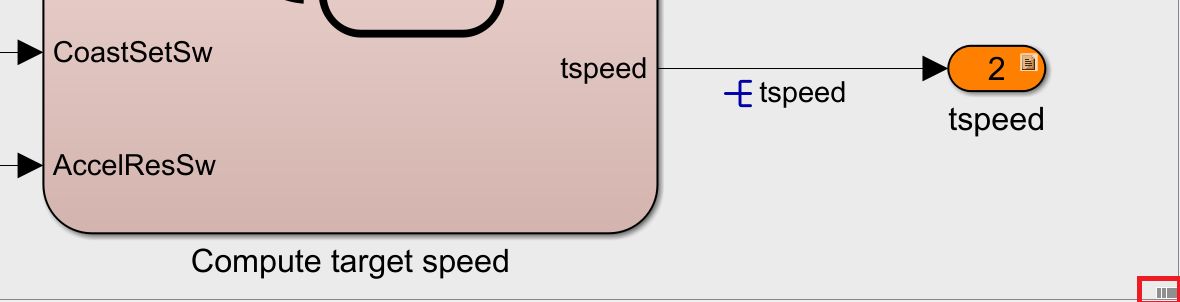

This will open a gallery with the available perspectives. Hover over the Requirements icon and click "Enter perspective"

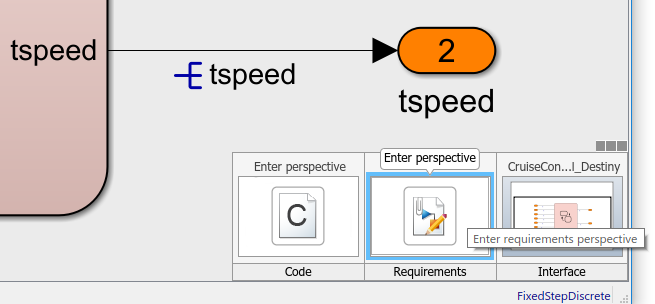

The Requirements Perspective is a view of the model's requirements traceability. Note the three key parts of the Requirements Perspective:

1) Badge icons for model elements that are linked to requirements

2) A requirements "browser" at the bottom of the canvas

3) The Property Inspector, with traceability information

[**Click here**](matlab:open_Requirements_Perspective_gif;) to open a short GIF animation showing the parts of the Requirements Perspective (**it will open outside of MATLAB**®).

Click on the requirements badge for the Cancel input, then click "show".

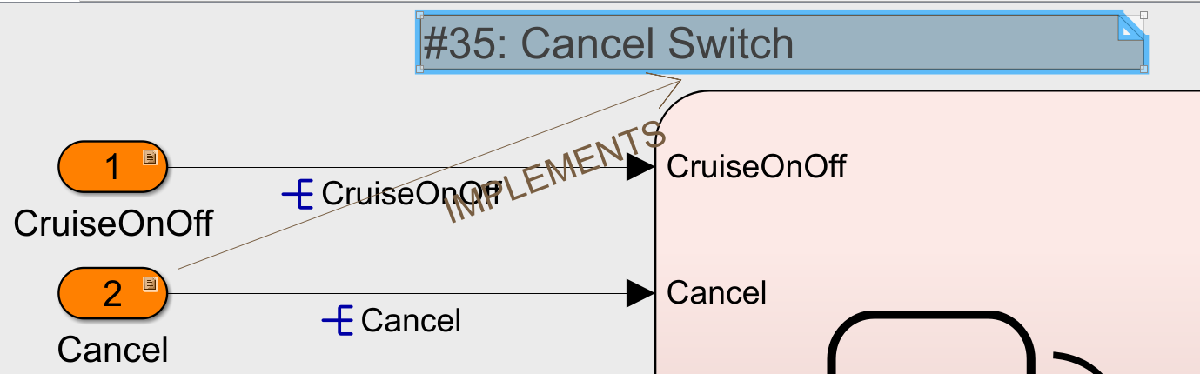

This is a requirements annotation. Click on the annotation "#35: Cancel Switch". Take a look at the Browser pane at the bottom. The associated requirement is highlighted, and the requirement Description will appear in the Property Inspector pane on the right.

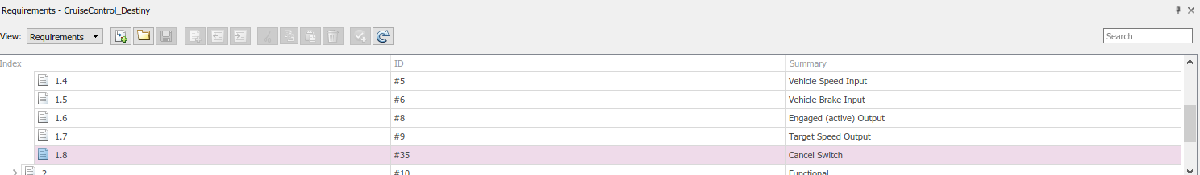

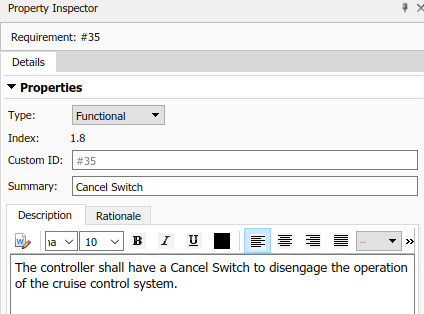

Let's save this model as a new version. [**Click here**](matlab:open_pod_model;) to open the copied model.

    1. Re-enter the Requirements Perspective.

    2. Click on the badge for the Cancel input and click "Show"

    3. In the browser, right click on Requirement 1.8 (ID #35) and click **Show in Requirements Editor**

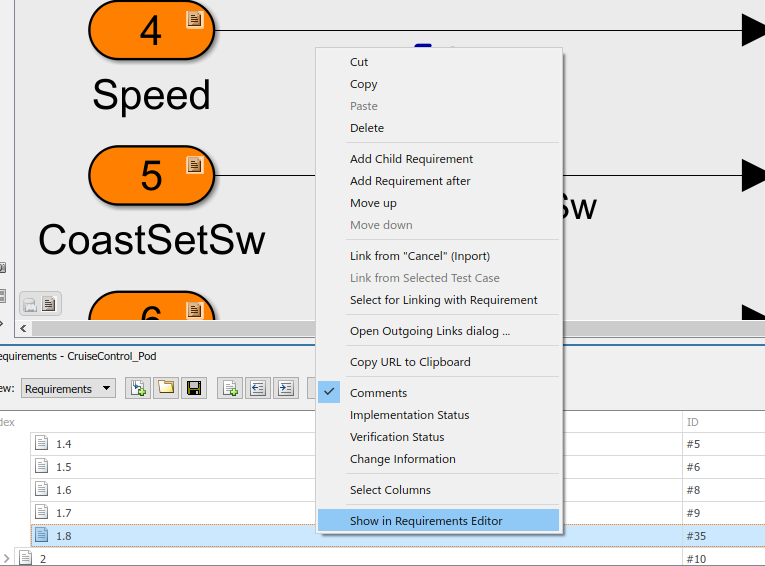

This will launch the Requirements Editor, which we can use to modify requirements.

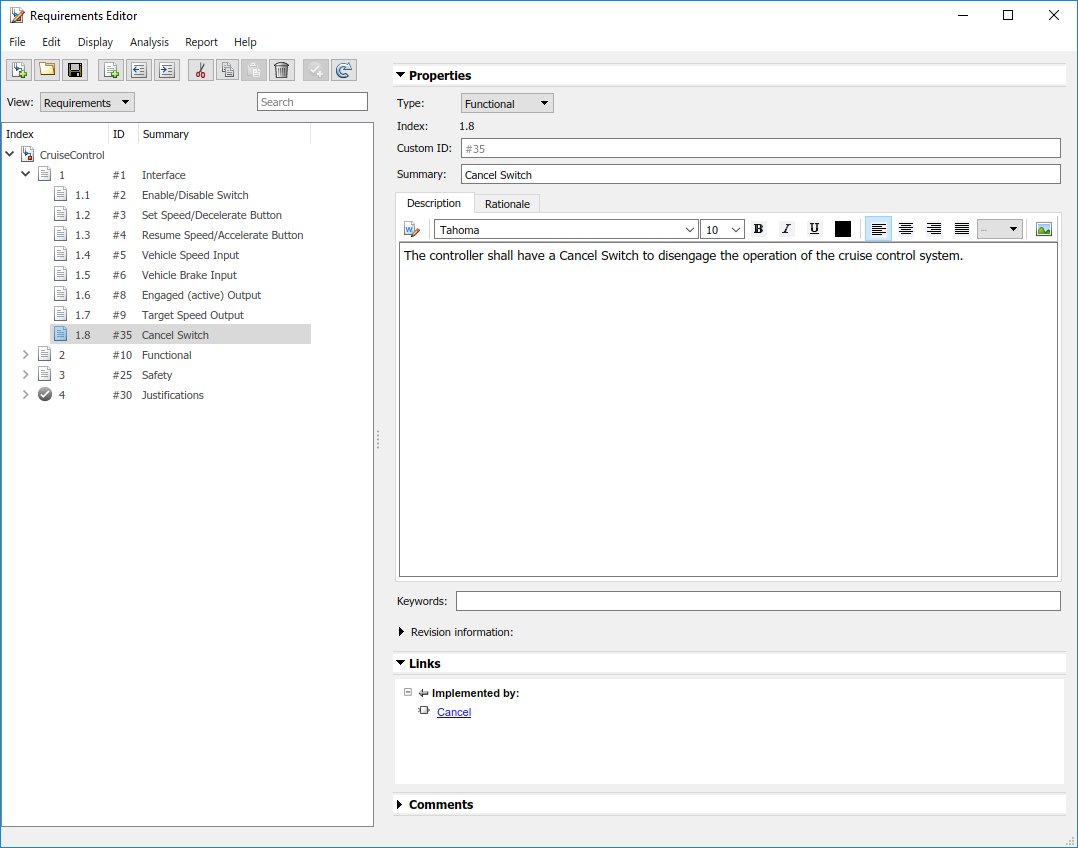

In this view, we see that the Cancel Switch requirement is part of the CruiseControl "Requirements Set". The requirement description is shown on the right side of the window, and its Links are shown in the bottom right. In this case, the link shows that the requirement is Implemented By the model element "Cancel".

A requirements set is a stand-alone file with an extension of .slreqx . A Simulink® model (.slx file) can have model elements linked to a requirements set. These links are stored in a traceability data file with an extension of .slmx.

**We need to delete the link and the requirement itself.**

- Hover over the Cancel hyperlink in the Links pane. A red "X" will appear. Click on the "X" to delete the link. In the pop-up dialog, confirm the deletion by clicking "Delete"

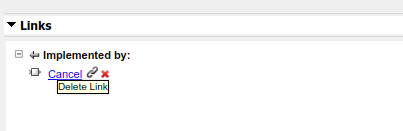

        2. Delete the requirement by selecting it in the left part of the window and press the Delete key

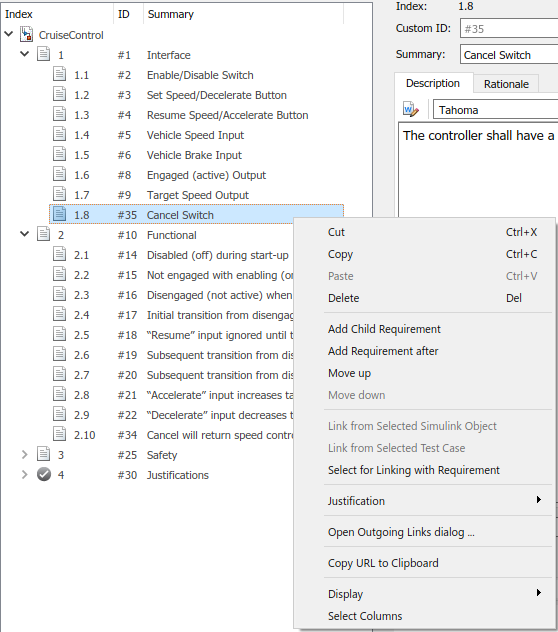

    3. Go back to the model. Make sure you are still in the Requirements Perspective. Note that the requirements badge for the Cancel input has disappeared.

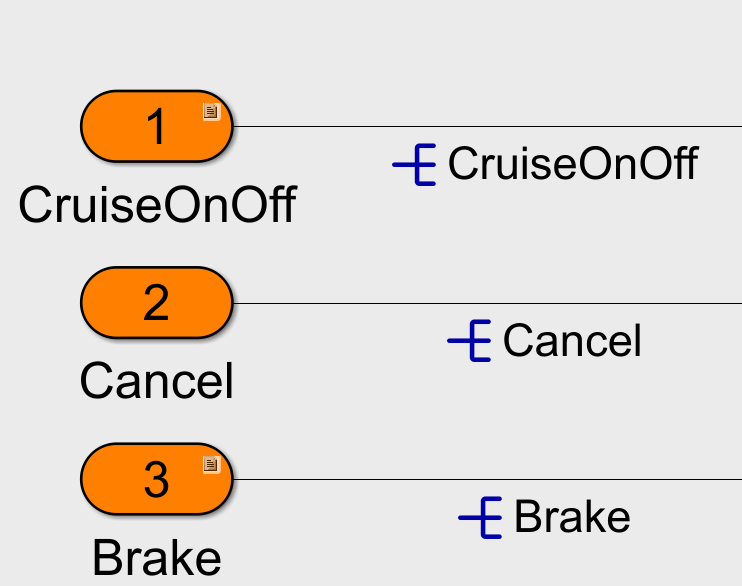

    4. Repeat Steps 1 and 2 for the second Cancel requirement. Before you delete the link, check and see where in the model the requirement is implemented.

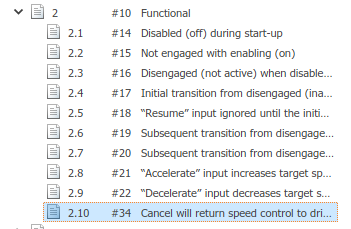

After you are done, it is time to make changes to the model! You should make two changes (hint: one of them involves a transition in a Stateflow chart).

If you get stuck, [**click here**](matlab:open_pod_final_model;) to open a final version of the model.

**Congratulations!** You have just successfully managed a requirements change and made model modifications.

In summary, Simulink® Requirements™ provides users with the ability to manage and author requirements directly in Simulink®. The key features are:

- **Requirements Perspective: **a view of the requirements and their links, including a Requirements Browser and Property Inspector

- **Requirements Editor**: a stand-alone requirements management tool to view and modify requirements sets

# Part 2: Check Model for Standards Compliance

**Farnswerth Automotive** has a rigorous design review process, which includes compliance with industry and internal modeling standards.

Let's make sure the model is compliant with these standards before going in for a design review with your peers.

## Step 1: Run Industry Standard Checks While Editing Model

Simulink® Check™ provides a feature called "Edit-Time Checking", which runs in the background while you edit your model. Issues are automatically identified in real time to enable timely fixes.

Edit-Time Checking is enabled via **Model Advisor**, which is a standard Simulink® feature.

Open the model again by [**clicking here**](matlab:open_edit_time_model) or running the following code:

open_system('CruiseControl_Model_Checks.slx');

To enable Edit-Time Checking, click on **Analysis -> Model Advisor -> Display Advisor Checks in Editor**

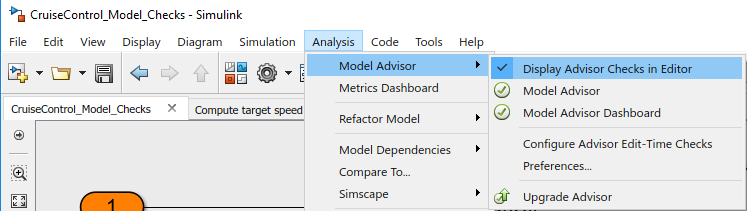

After Edit-Time Checking has been enabled, the checks have been automatically run and the results displayed on the model canvas.

Note the name violation found for the subsystem "Compute target speed".

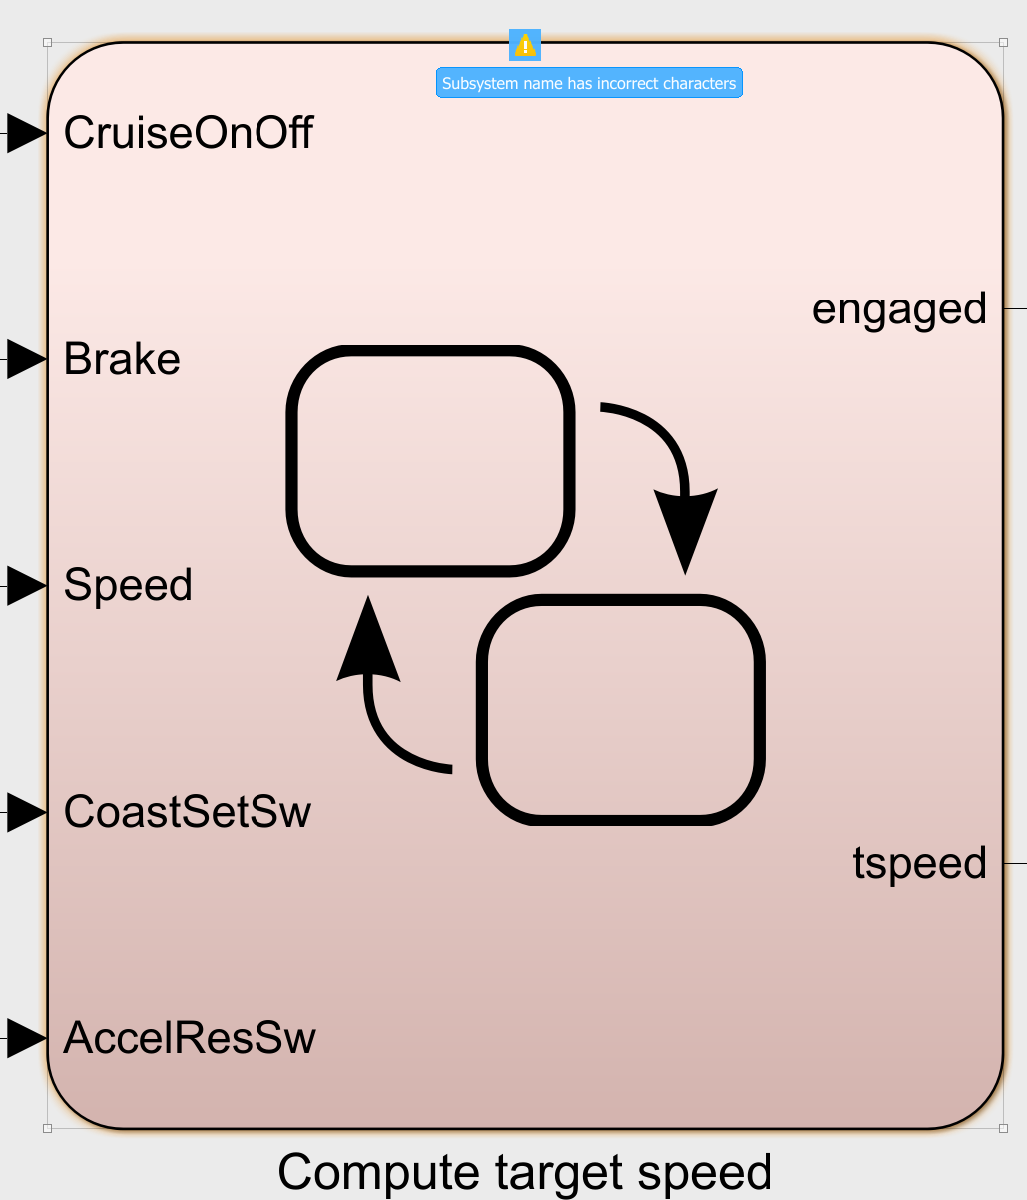

Open the Stateflow chart to find another violation regarding the "ON" state:

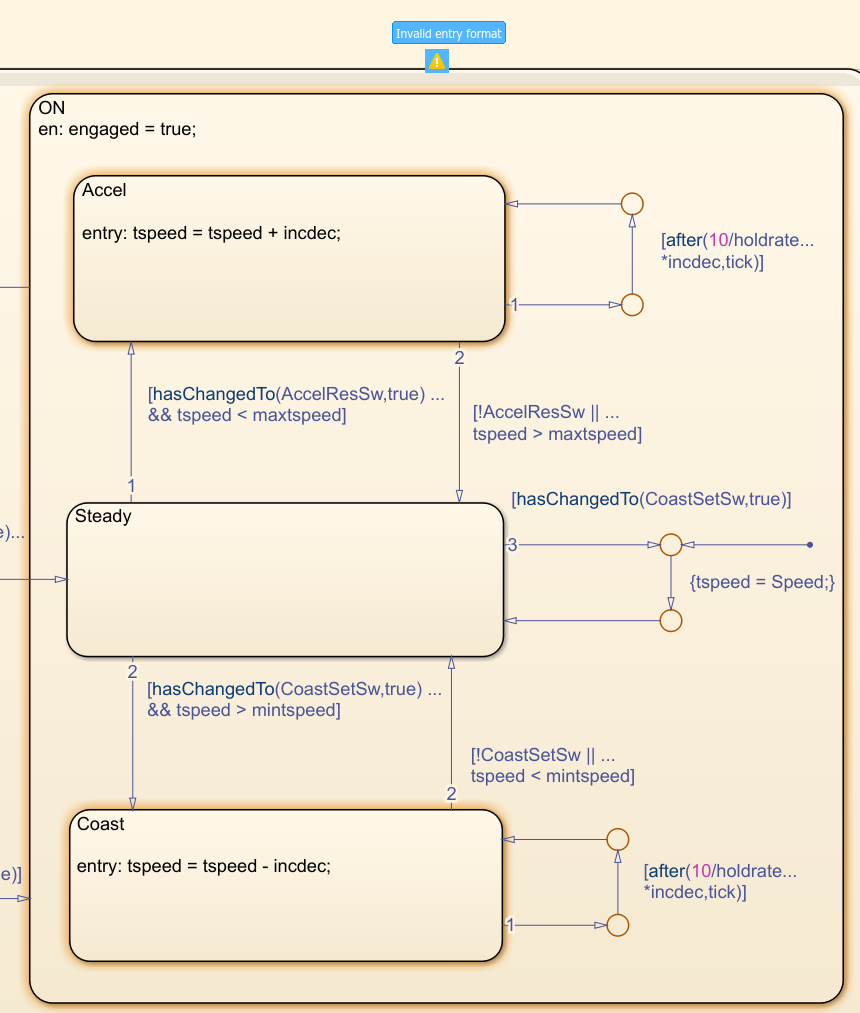

Clicking on the warning provides information on possible fixes

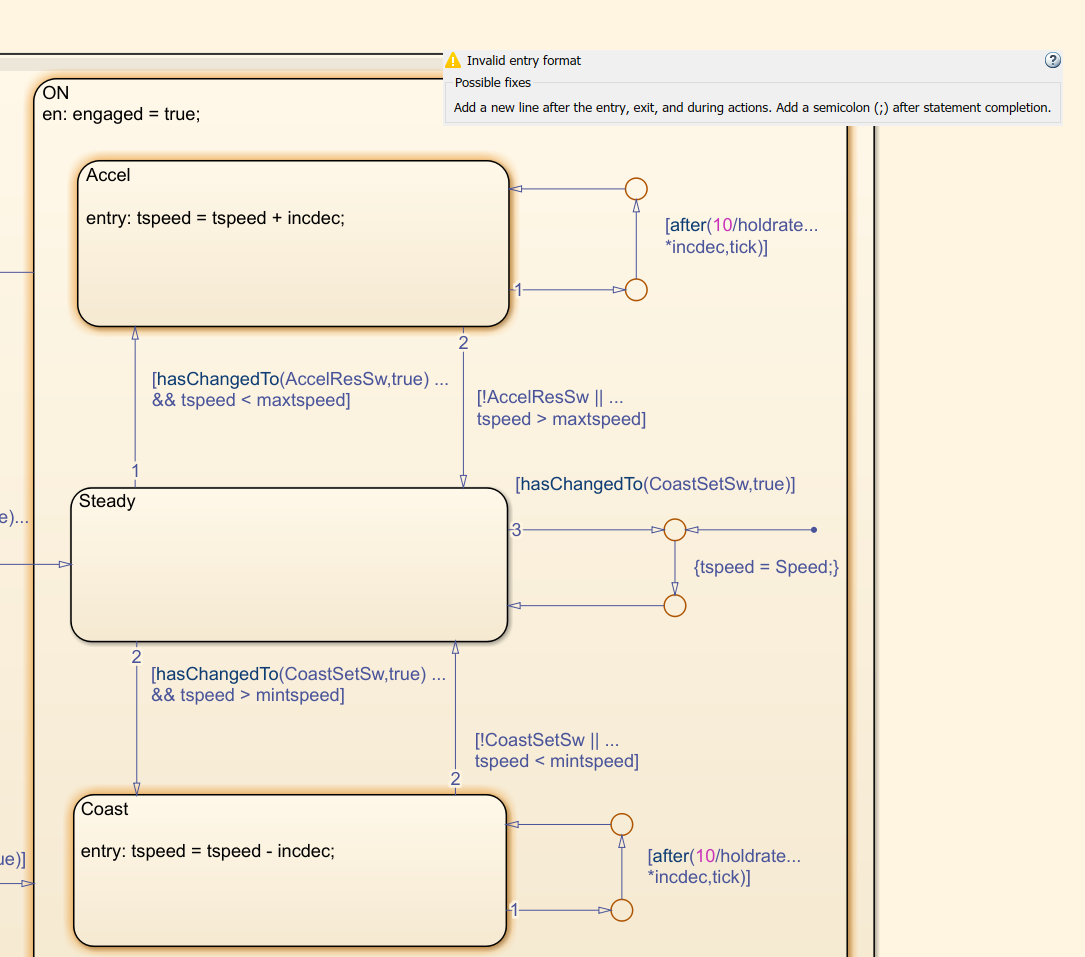

These errors are fairly straightforward to fix. Try addressing them yourself. When you're done, move on to Step 2.

**Note**: If you save a model with Edit-Time Checking enabled, it will be automatically enabled when the model is re-opened.

## Step 2: Run Custom Checks

Simulink® Check™ provides the ability to add custom model checks. This can be helpful when your company has internal modeling standards, sometimes documented in a style guide.

Custom Checks are added via the Model Advisor API and the **sl_customization.m **file. 

In this example, we will use Model Advisor to run three Custom Checks that are based on the Farnswerth Automotive Style Guide. These are defined in **sl_customization.m** . This sl_customization.m file can be used for various purposes including but not limited to verification activities. For instance, it can be used to change block fonts, block colors and Simulink® windows screen colors among other things.

The internal tools team at Farnswerth Automotive has already added the code to run these checks in **sl_customization.m . **

For now, we just need to enable the custom checks to run in Model Advisor. After finishing Step 2, feel free to view the code that created the Custom Checks by running [edit sl_customization.m](matlab:edit sl_customization.m) in the MATLAB® Command Window. You can also [create your own checks](https://www.mathworks.com/help/slcheck/ug/defining-custom-checks.html).

Let's run some MATLAB® code to enable Custom Checks (click **Run Section **in the Live Editor tab)

bdclose('all') % close all open models
Advisor.Manager.refresh_customizations; % refresh customizations
open_system('CruiseControl_Model_Checks.slx'); % reopen the model

In the model, re-open Model Advisor by clicking on **Analysis -> Model Advisor -> Model Advisor**

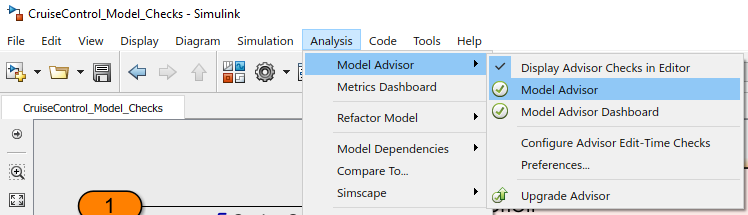

In the System Selector window, select **CruiseControl_Model_Checks**

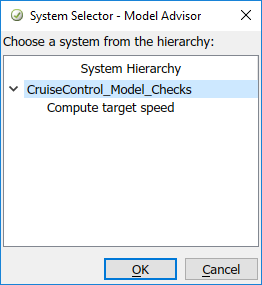

In the Model Advisor window, you will see a folder for "By Product". This folder contains a set of checks based on Simulink® products used. It also contains a subfolder called "**Custom Checks**."

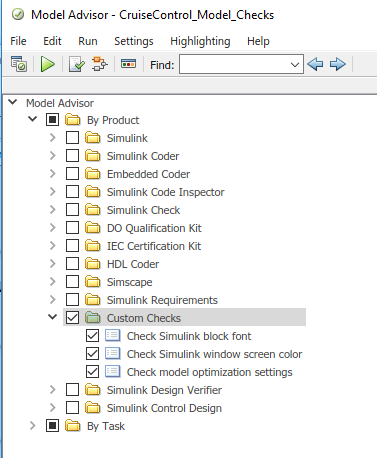

In this example, three Custom Checks have been created. These checks correspond to internal modeling standards at Farnswerth Automotive.

Let's run these checks to ensure compliance:

- Select the "Custom Checks" folder to enable all checks in the folder

- Click "Run Selected Checks"

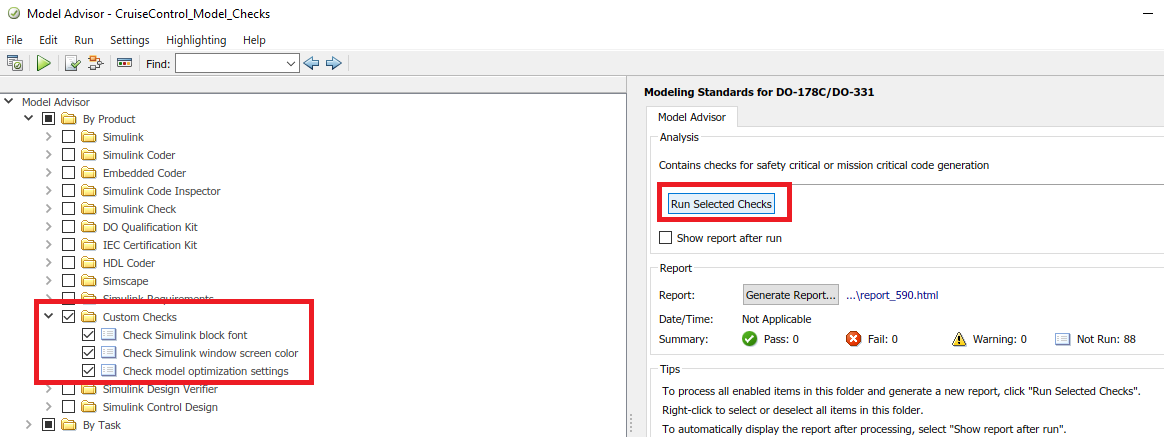

After the checks are performed, the results appear in the Model Advisor window.

One of the checks passed, one has failed, and one has a warning.

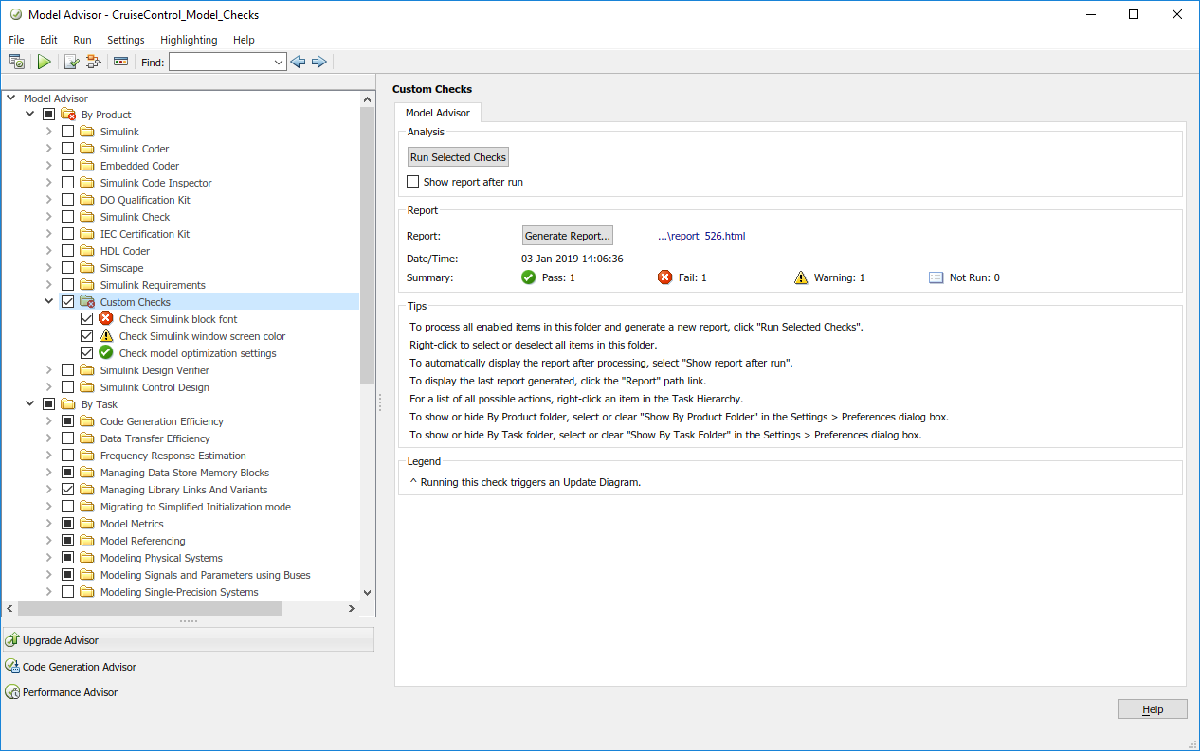

Click on the failed custom check "**Check Simulink blonk font**" to see more details on the results.

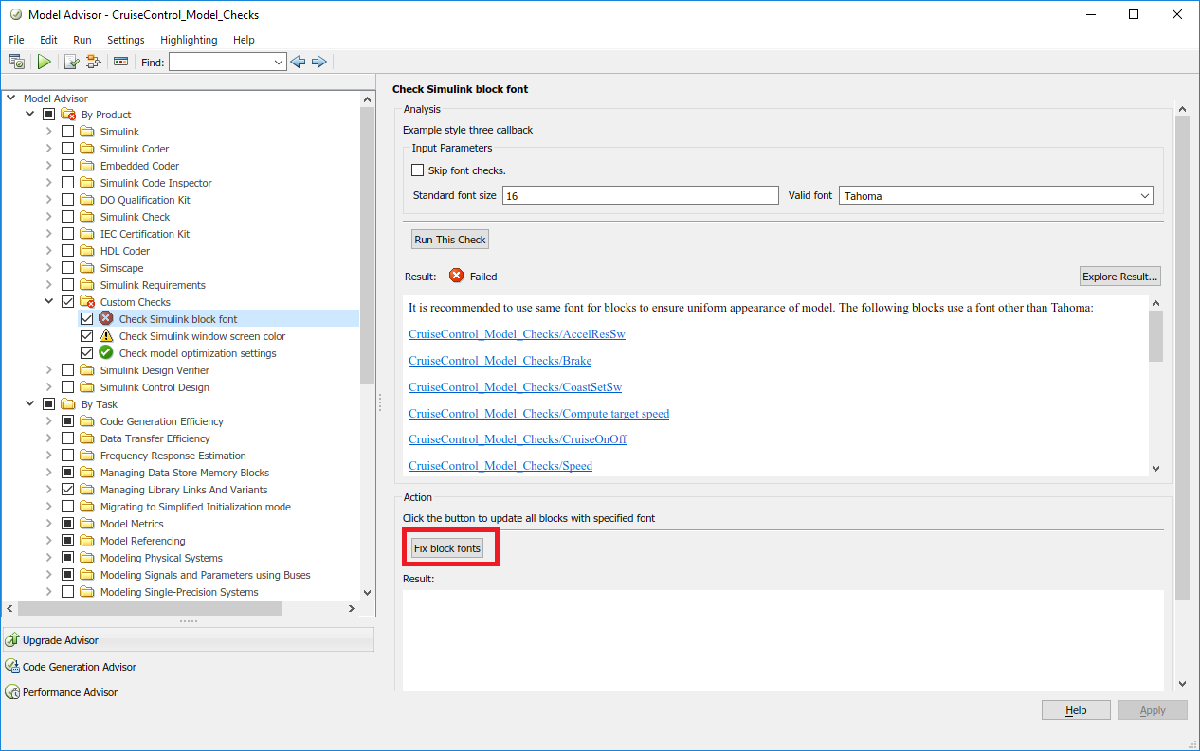

For this custom check, and automatic "fix" is provided. For these types of checks, Model Advisor is given a set of pre-defined instructions on how to automatically fix certain errors.

These instructions are defined in **sl_customization.m**

Click on "Fix block fonts".

Fonts are automatically changed based on the instructions provided for the custom check. 

In this case, fonts have been changed to Tahoma to be compliant with the Farnswerth Automotive Style Guide.

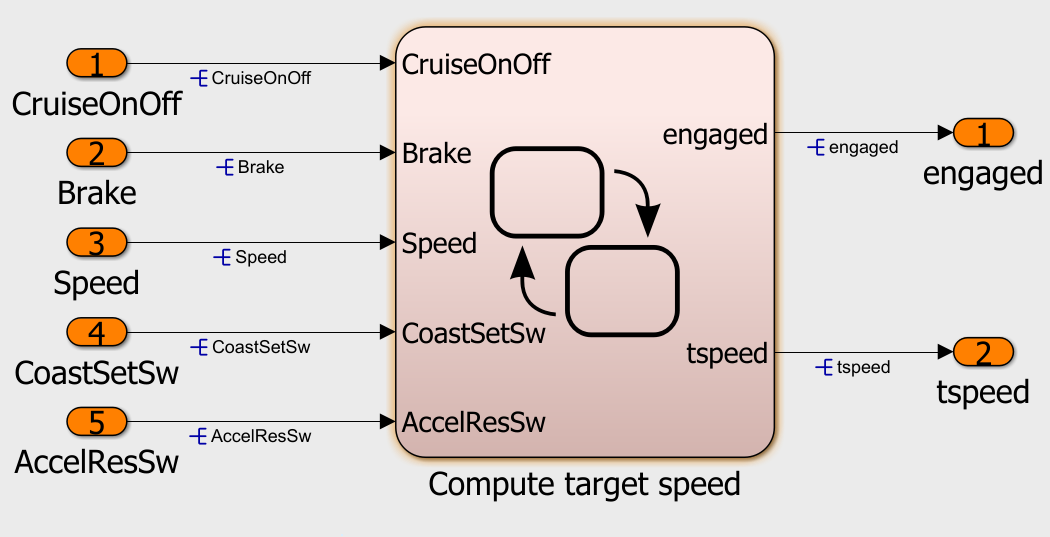

In summary, Simulink® Check™ provides:

- **Edit-Time Checking** to catch mistakes while working on the model

- **Custom Checks** to ensure that your model complies with your organization's standards and guidelines

Simulink® Check™ provides other useful features, such as the Metrics Dashboard. [**Click here**](https://www.mathworks.com/products/simulink-check.html) to learn more.

# Part 3: Check Model for Design Errors

You’re almost done! We’ve just finished checking for model standards compliance. Before we stand in front of the team at tomorrow’s design review, let’s make sure there aren’t any design errors.

Simulink® Design Verifier™ is a static analysis tool that uses formal methods to detect errors. The tool can check for several types of design errors, including division-by-zero, integer overflow, and dead logic. 

In this example, we will only look for division-by-zero errors. 

Division-by-zero occurs when a zero is used in the denominator of a division operation, which causes a run-time error.

In traditional, simulation-based testing, it can be difficult to create tests that reveal division-by-zero errors.

Simulink® Design Verifier™ uses static analysis to formally analyze our model for us to check if there are any unreachable states or transitions and if there are any possible division-by-zero design errors. The best practice is to run these design error checks before executing the simulation based tests to catch errors early and have a more efficient testing workflow. Simulink® Design Verifier™ uses formal methods which means that the analysis is "exhaustive" compared to simulation-based testing which is "non-exhaustive".

We will be using Simulink® Design Verifier™ in Design Error Detection mode to analyze for division-by-zero runtime errors.

## Analyze Model for Potential Division-by-zero Errors

Open the model by [**clicking here**](matlab:open_divByZero_model) or by running the following MATLAB® code:

bdclose all
clear
open_system('CruiseControl_DivByZero')

#### Enable Design Error Detection Mode

First, let's set the mode to Design Error Detection.

- Click on **Analysis -> Design Verifier -> Options**

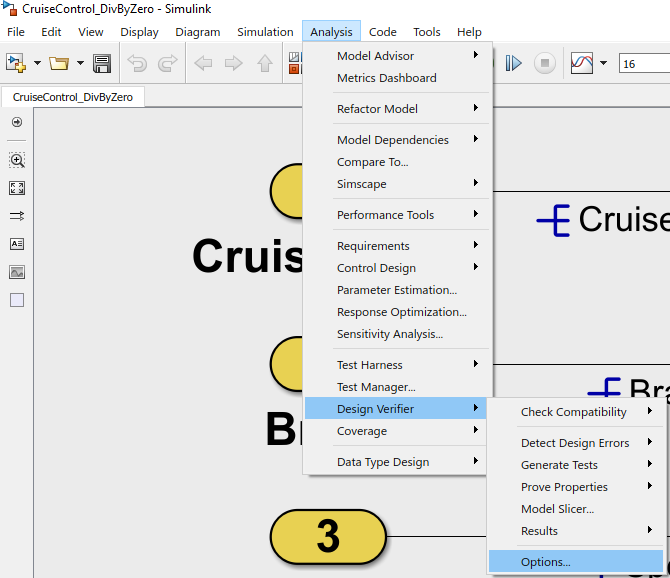

This will open the Configuration Parameters window.

2. In the Design Verifier section, select "Design Error Detection", then select "Division by zero".

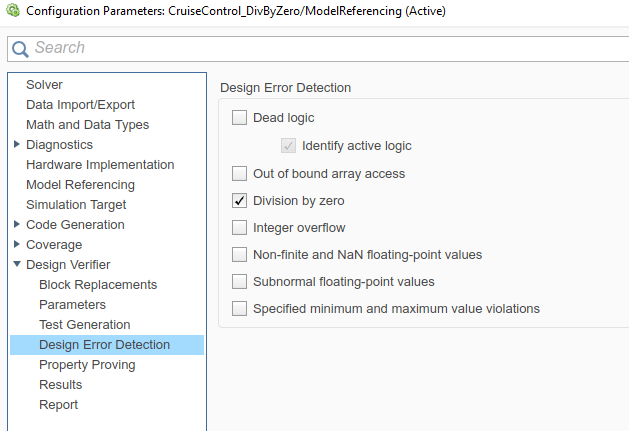

3. Click "Apply"

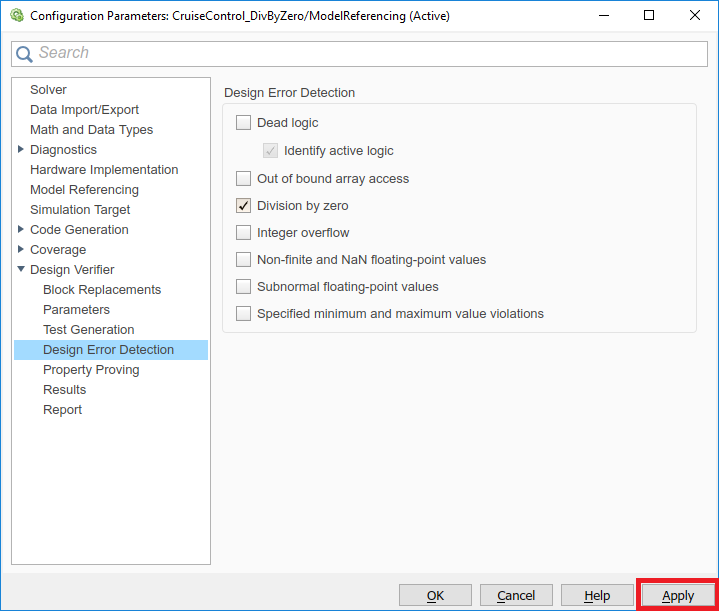

#### Using Parameters in Analysis

The model has several tunable parameters, each of which has its own range. A good practice is to include the parameter ranges in the analysis, since an inadvertent change in a parameter's value may cause a run-time error.

Simulink® Design Verifier™ provides us with this ability through the Parameters pane in the Configuration Parameters window.

By using this feature, a parameter will essentially be treated like a signal during analysis, with its own range, rather than as a constant.

1. Click on the **Parameters **navigation link

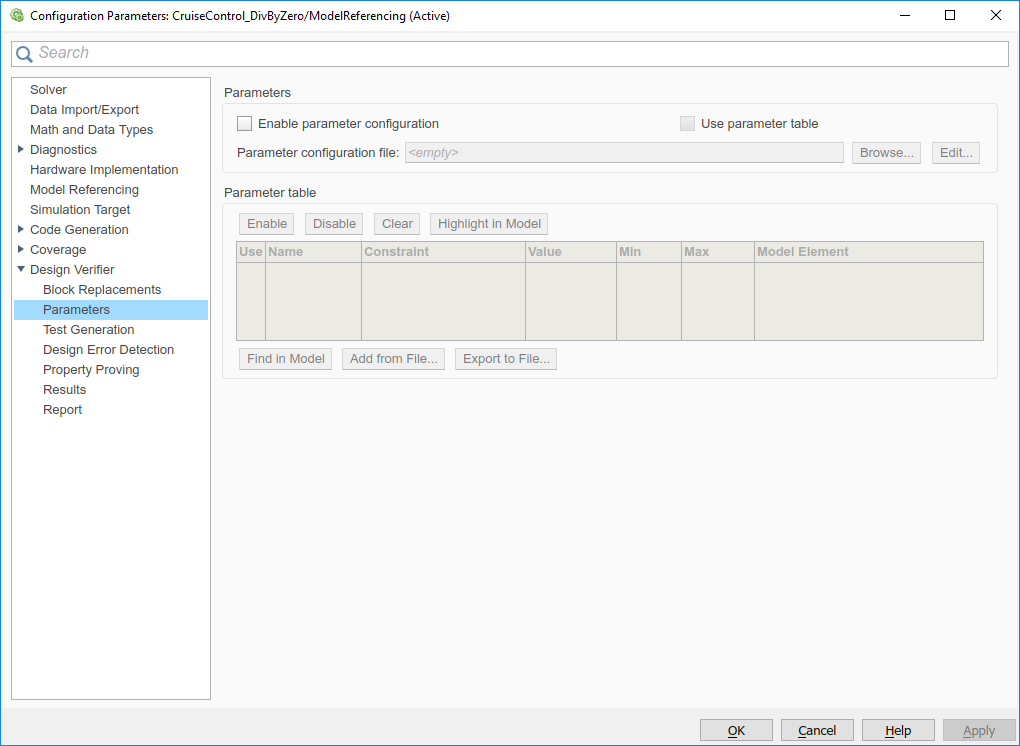

2. Select **"Enable parameter configuration"** and **"Use parameter table"**

3. Select **Find in Model** to populate the parameter table. This will populate the table with all tunable parameters in the model.

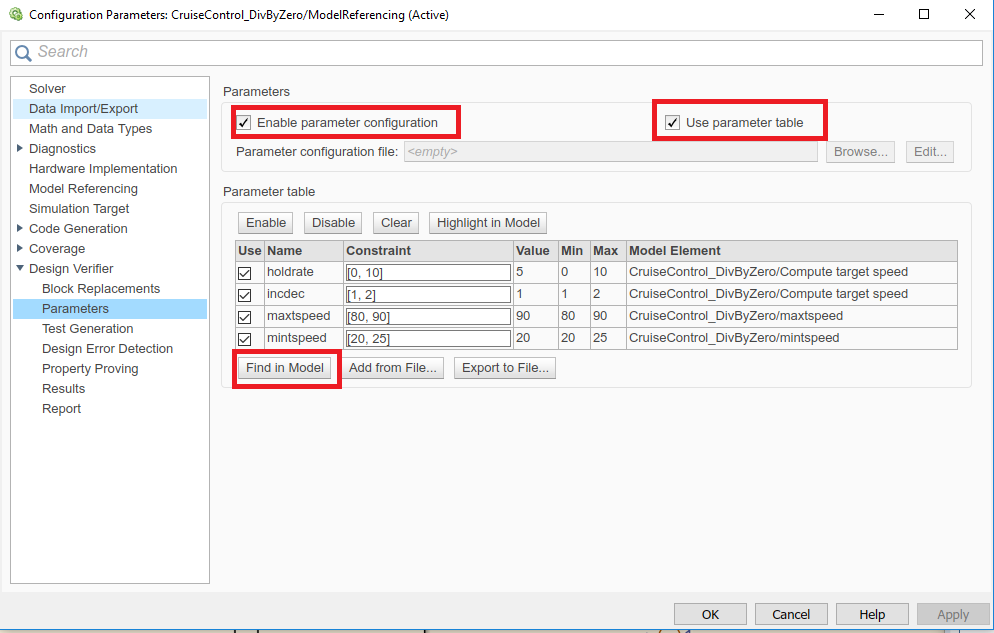

4. Click **Apply**

#### Run Analysis to Check for Design Errors

1. Navigate back to the Design Verifier pane in Configuration Parameters

2. Click on **Detect Errors**

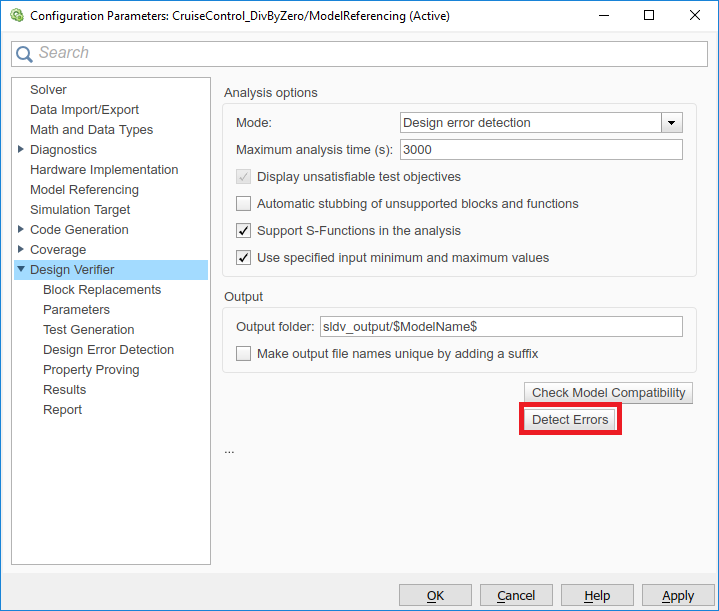

#### Analyze Results

After Simulink® Design Verifier™ has completed its analysis, look at the Results Summary window.

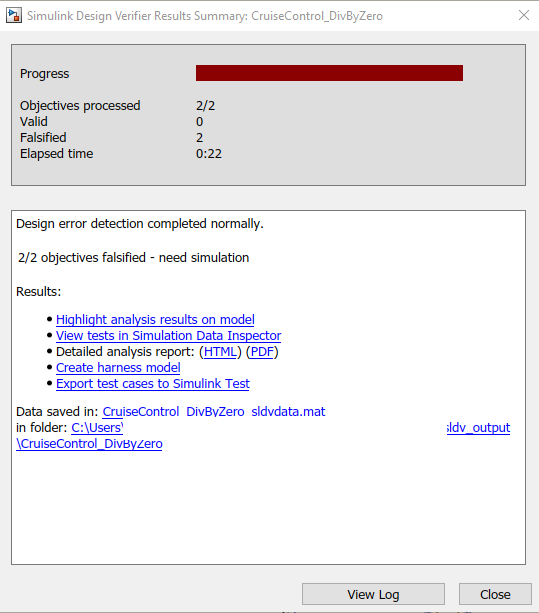

The Results Summary window provides an overall summary of the analysis.

In this case, Simulink® Design Verifier™ found two instances where a division-by-zero may occur. These are called "objectives." Think of an objective as a problem the tool is trying to solve. Since the model has two division operations in it, Simulink® Design Verifier™ identifies two problems it is trying to solve for. The problem is: could a division-by-zero occur for either operation?

The Results Summary also provides several ways to review the results in the "Results" section.

- Click on "**Highlight analysis results on model**"

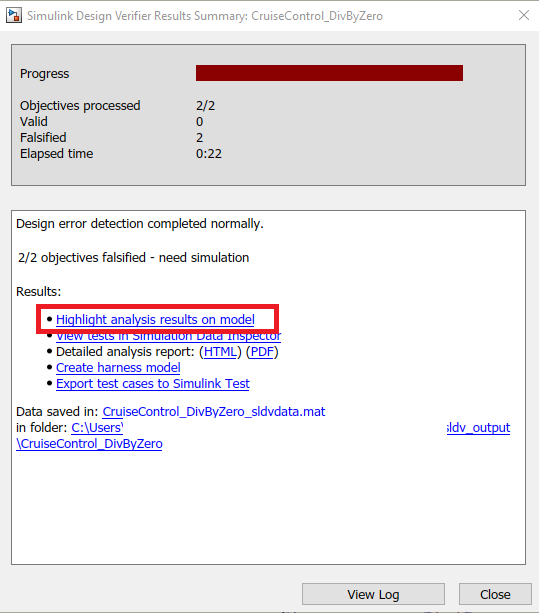

You will then see the high level view of the model.

Notice the red highlighting around the "Compute target speed" Stateflow chart.

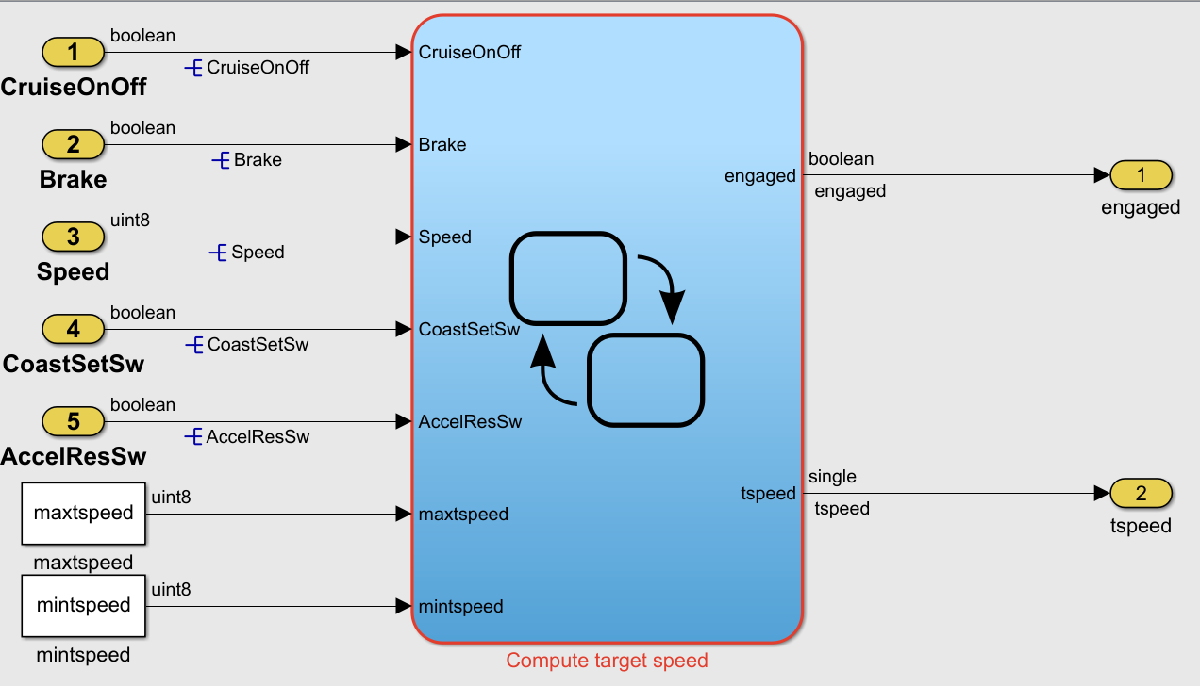

2. Double click on the state machine.

Within the Stateflow chart, you should see two transitions in the ON state highlighted in red.

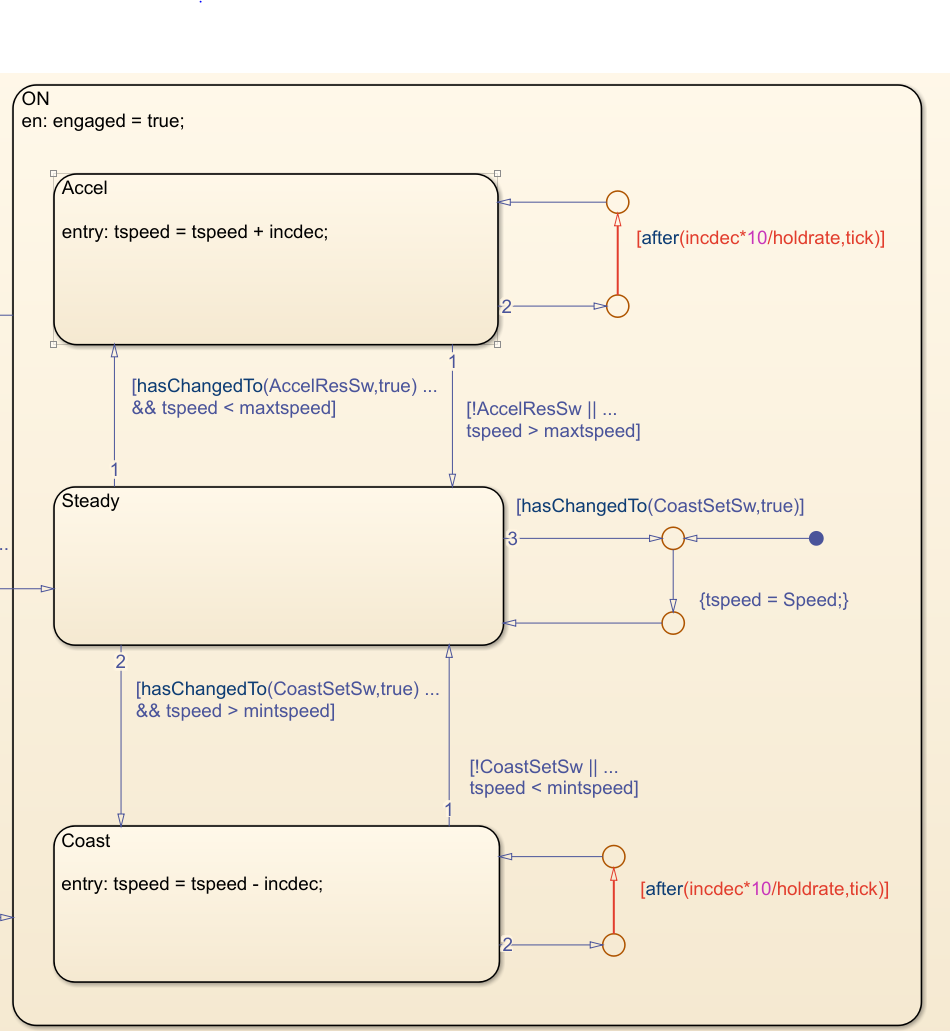

The design error has something to do with the "holdrate" parameter, which is used in both division operations.

Let's look in a detailed report to learn more about how Simulink® Design Verifier™ used this parameter in the analysis.

3. In the Results Summary window, click **Detailed analysis report (HTML)**

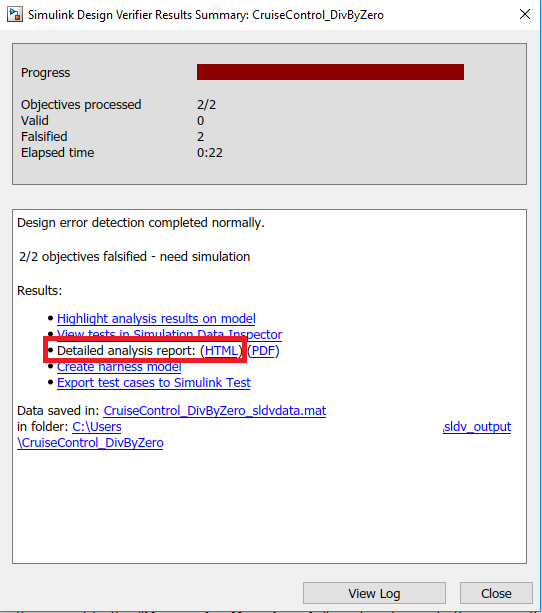

4. In the HTML report, click on **"5. Design Errors"** in the Table of Contents. This will take you to the section describing the design errors found.

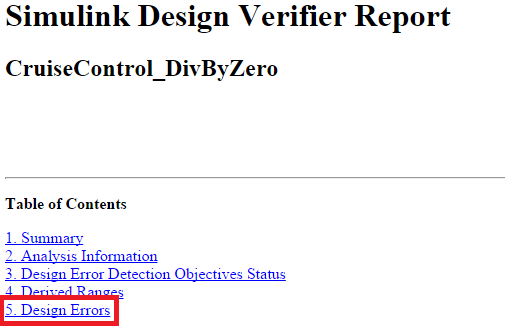

Let's look at the first design error in Section 5:

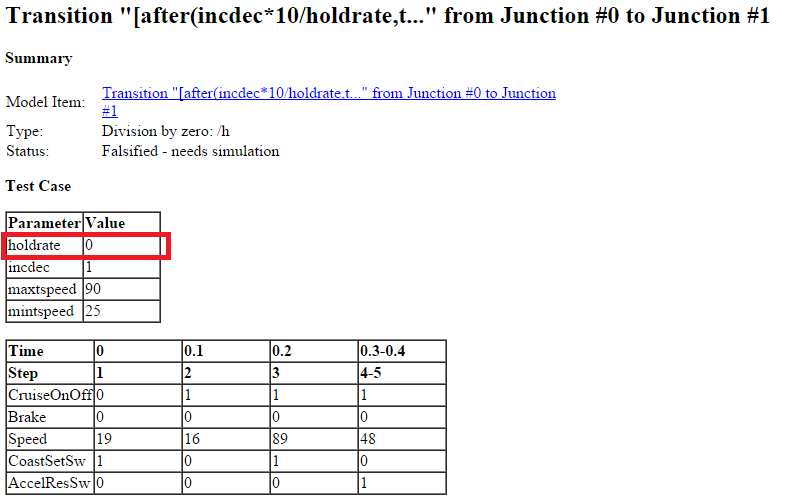

A test case has been created which shows how a division-by-zero could occur.

Notice that the value of holdrate is set to 0 in the Test Case. This is because the minimum value of the holdrate parameter, in the parameter's range, is set to 0.

Let's fix the issue by changing the minimum value to 1 by running the following code

holdrate.Min = 1

holdrate =   Parameter with properties:

          Value: 5
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'uint8'
            Min: 1
            Max: 10
           Unit: ''
     Complexity: 'real'
     Dimensions: [1 1]



Save the model.

Navigate back to the Parameters tab in Design Verifier Settings. We need to tell Simulink® Design Verifier™ to look for the new parameter value for holdrate.

Highlight the holdrate row, and click the "Clear" button.

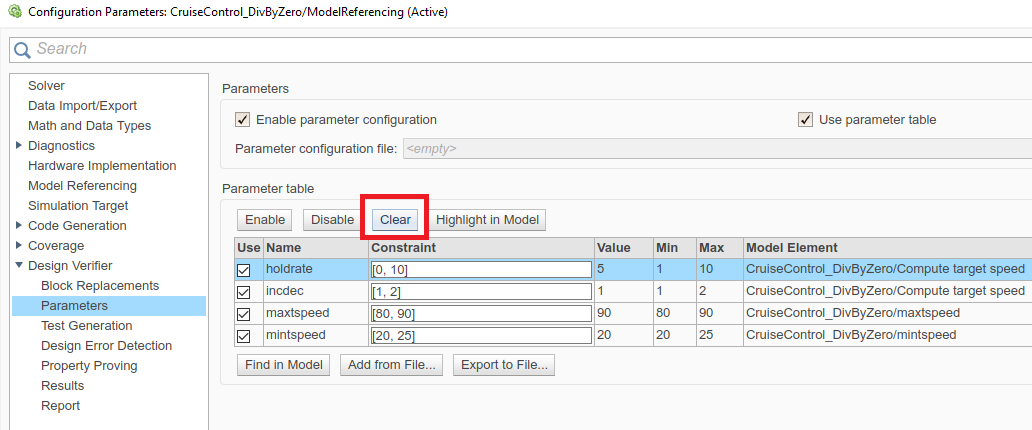

Click "Find in Model"

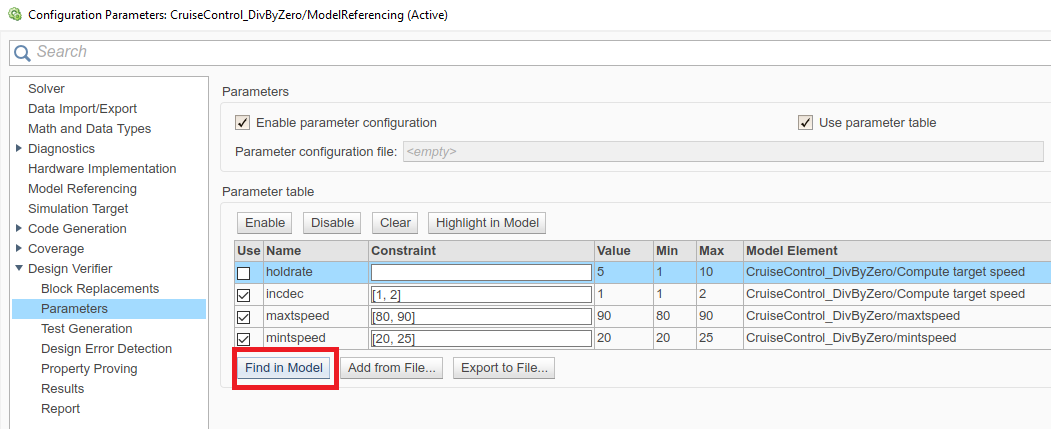

The parameter table is then updated to show the new minimum value for holdrate.

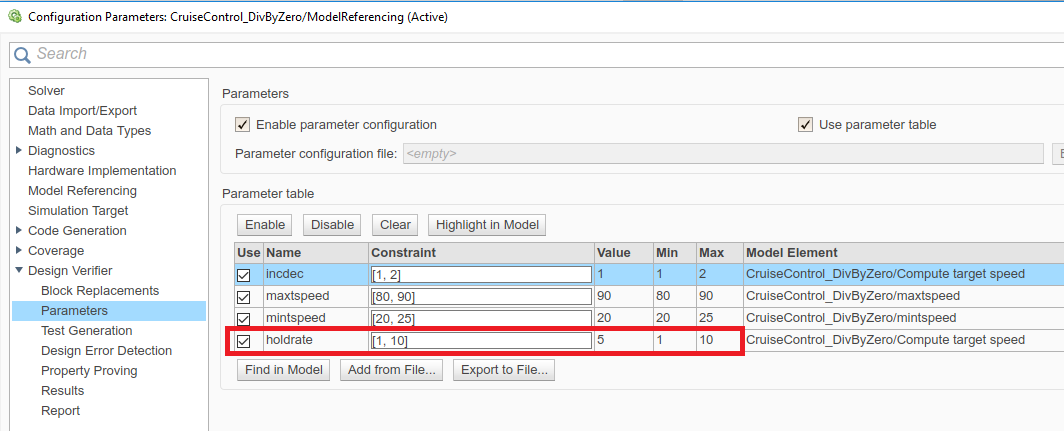

If you re-run the analysis, the division-by-zero is no longer possible.

**Congratulations!** You have successfully analyzed a model for division-by-zero. Simulink® Design Verifier™ includes several other features, such as Dead Logic detection, automatic test generation, and property proving. Be sure to check out these other features.

# Summary

In this example workflow, we:

- ensured the design is traceable to requirements

- ensured the design complies with industry and company standards

- identified and corrected a design error

You should now be ready to step in front of your team at tomorrow's design review. Good luck!